# Weight Loss dataset

## **Michael Algarra**

This data was collected from a crowd-sourced experiment looking at the effects of various parameters on weight loss. Data was gathered either through the use of self-tracking apps (such as activity trackers like FitBit (TM)) or through questionares. The study lasted 3 months and the values presented here have been aggregated and patients with missing data have been dropped, along with any potentially identifiable information. Our overall goal is to find which parameters are most associated with weight loss.

**Data Description** The data is given in an sqlite database named **weightdata.sqlite**, with a single table, **patient**.

- age: Patient's age at the start of the study.

- gender: Self identified gender.

- height: The patient's height (in inches).

- initweight: The weight of the patient at the start of the study (in pounds).

- calintake: The average number of calories consumed per day.

- jobstatus: The self-identified job status, either Active or Inactive.

- timecardio: The average minutes of cardio (per week).

- timeresist: The average minutes of resistence training (per week).

- sleep: The average amount of sleep (hours) per day.

- steps: The average number of steps per day (counted using phone accelerometers).

- deltaweight: The change in weight after the 3 month study (in pounds).

## Variable names

- d: Database connection.

- dbdata: All patient data, represented as a Matlab structure array.

- data: All patient data, represented as a Matlab table object.

- numActive/numInactive: Designates count of active/inactive working patients

- calin35older: Average calorie intake for those 35 and up.

- h~,pval~,p~: pval and p were used to designate p values depending on case, h logical used to determine if significant or not.

- forPreference: Selects data of patients that had greater than 0 minutes of exercise, be cardio or resistance, per week.

- r~,r2~: r is the correlation coefficients acquired, whilst r2 is the R^2 value acquired given some cases.

- trend: trend is the polyfit calculation trying to fit the two variables with a trendline. Gives both slope and y intercept.

- basalcalories: the calculated basal calories (metabolism) for each patient

- exercisecalories: the calculated exercise calories burned for each patient

- netcalories: The calorie intake minus both the basal calories nad the exercise calories.

- X: each of the columns except the ID and Delta weight from the table, to conduct a multivariate analysis with

- w: the output of beta values from the multivariate analysis.

## Connect to the database

addpath("/Users/mikealgae/Dropbox/bmes.ahmet");
dbfile=bmes.downloadurl('https://sacan.biomed.drexel.edu/lib/exe/fetch.php?rev=&media=course:cbe:hw3db:weightdata.sqlite');
d=bmes_db(dbfile,'bmessqlitemex');

## Data Statistics using SQL

Use SQL queries to answer each of the following questions:

**How many patients have Active jobstatus, and how many have Inactive?**

numActive = d.query('SELECT count(*) as numActive FROM patient WHERE jobstatus="Active"');
numInactive = d.query('SELECT count(*) as numInactive FROM patient WHERE jobstatus="Inactive"');
fprintf("There are %d active patients and %d inactive patients",struct2array(numActive),struct2array(numInactive))

There are 129 active patients and 121 inactive patients

**What is the average calorie intake of the patients who are 35 years and older?**

calin35older = d.query('SELECT AVG(calintake) as numActive FROM patient WHERE age>=35');
fprintf("The average calorie intake for those 35 and older is %f",struct2array(calin35older))

The average calorie intake for those 35 and older is 1667.063176

**What is the average age of the patients with Active and Inactive job statuses? **

ageActive = d.query('SELECT AVG(age) as numActive FROM patient WHERE jobstatus="Active"');
ageInactive = d.query('SELECT AVG(age) as numInactive FROM patient WHERE jobstatus="Inactive"');
fprintf("The average ages are %f for active patients and %f for inactive patients.",struct2array(ageActive),struct2array(ageInactive))

The average ages are 33.023256 for active patients and 32.884298 for inactive patients.

## Convert the data into a Matlab table for use in the rest of this file.

dbdata = d.query('SELECT * FROM patient');
data = struct2table(dbdata);

## Gender specific differences in excercise preference.

Use the data to answer whether there are gender specific differences in excerise preference (resistence vs cardio). In this analysis task only, exclude/remove patients that did not have any resistance **or **cardio exercise (where resistance **or** cardio values are zero).

% select only the patients that have cardio or resistance exercises
forPreference = data(data.timecardio(:)~=0 | data.timeresist(:)~=0,:);

% check if there is a preference between the two means, using a t test
% for males
[hM, pvalM]= ttest2(forPreference.timecardio(strcmp(forPreference.gender,"Male"),:),forPreference.timeresist(strcmp(forPreference.gender,"Male"),:));
% for females
[hF, pvalF]= ttest2(forPreference.timecardio(strcmp(forPreference.gender,"Female"),:),forPreference.timeresist(strcmp(forPreference.gender,"Female"),:));

if hM==1 && hF==1
    fprintf("By comparing cardio versus resistance training times for each gender, I found that there was a stastical difference between the two\n" + ...
    "specific exercise training times with a p value of %d for Men and %d for Women.",pvalM,pvalF)
end

By comparing cardio versus resistance training times for each gender, I found that there was a stastical difference between the two
specific exercise training times with a p value of 5.688177e-85 for Men and 2.132660e-123 for Women.

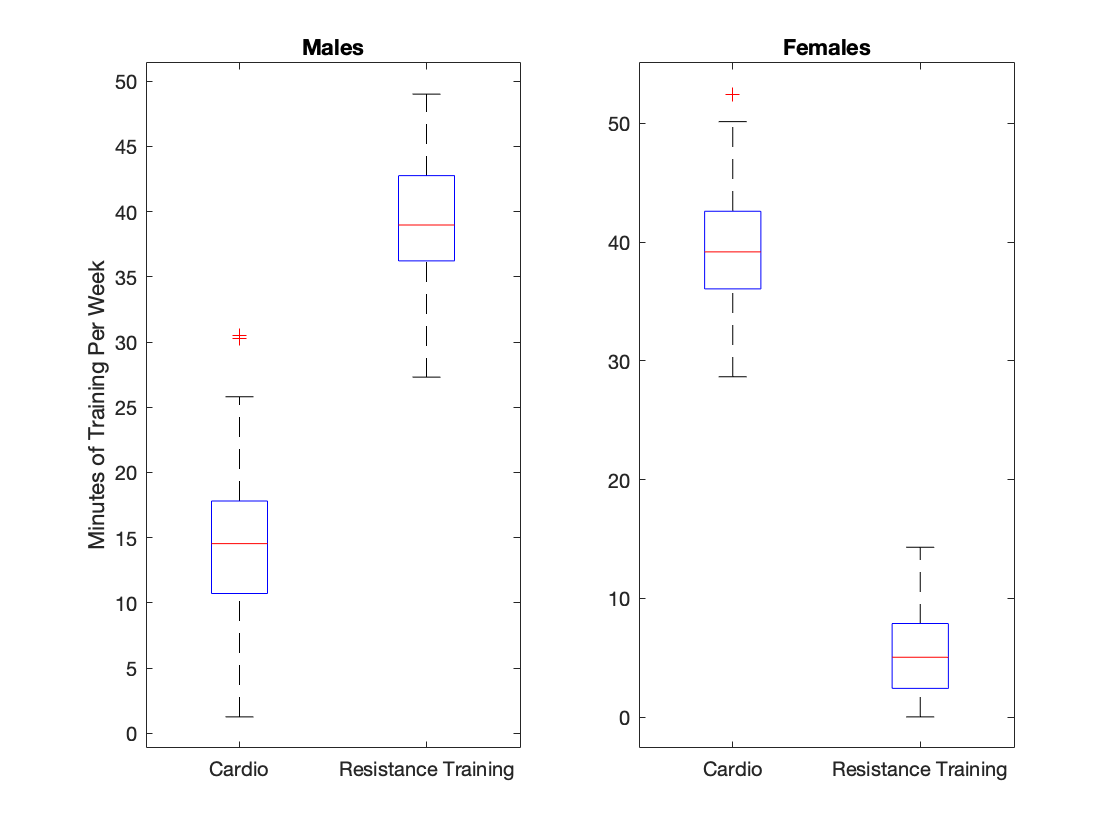

% graphically showing it
figure, subplot(1,2,1)
boxplot([forPreference.timecardio(strcmp(forPreference.gender,"Male"),:),forPreference.timeresist(strcmp(forPreference.gender,"Male"),:)],["Cardio","Resistance Training"])
hold on
title("Males"), ylabel("Minutes of Training Per Week")
subplot(1,2,2)
boxplot([forPreference.timecardio(strcmp(forPreference.gender,"Female"),:),forPreference.timeresist(strcmp(forPreference.gender,"Female"),:)],["Cardio","Resistance Training"])
hold on
title("Females")
hold off

**Figure Caption: **This shows the obvious difference between males and females of preferred exercise per week for this training. A t-test calculated concluded the difference with over a 99% confidence for both.

## Differences between job status.

Use the data to answer whether the job-status influences the average number of steps a subject takes per day and the average number of calories consumed. Does jobstatus effect the number of steps a subject takes per day? Does jobstatus effect the average number of calories the subject consumes?

% let's start with job status and number of steps
% break into active and inactive
dataActive = data(strcmpi(data.jobstatus,'active'),:);
dataInactive = data(strcmpi(data.jobstatus,'Inactive'),:);
% t test
[hAI, pAI] = ttest2(dataActive.steps,dataInactive.steps);
fprintf("There is a significant difference between the daily steps taken between people actively working (active) versus those that are not (inactive),\nwith a 99%% confidence and a p value of %d",pAI)

There is a significant difference between the daily steps taken between people actively working (active) versus those that are not (inactive),
with a 99% confidence and a p value of 2.562871e-38

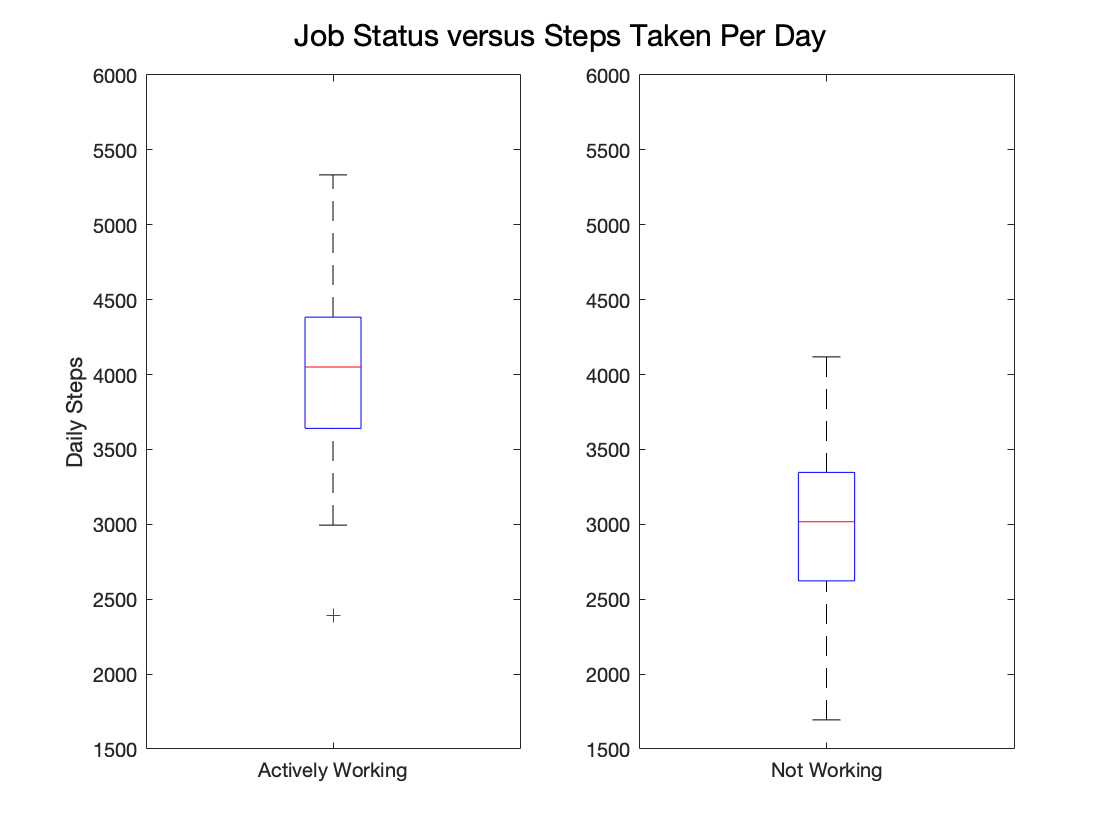

figure
subplot(1,2,1)
boxplot(dataActive.steps)
xticklabels("Actively Working"), ylabel("Daily Steps"),ylim([1500, 6000])
subplot(1,2,2)
boxplot(dataInactive.steps)
xticklabels("Not Working"), ylim([1500, 6000])
sgtitle("Job Status versus Steps Taken Per Day")

**Figure Caption: **This shows the significant difference in means between those working and those not working. There is a clear distinction in that those working have on average about 1000 more steps per day than those not working.

% For Job status versus calories consumed
[hCC, pCC] = ttest2(dataActive.calintake,dataInactive.calintake);
fprintf("There is a significant difference between the daily calories ingested taken between people actively working (active) versus those that are not (inactive),\nwith a 99%% confidence and a p value of %d",pCC)

There is a significant difference between the daily calories ingested taken between people actively working (active) versus those that are not (inactive),
with a 99% confidence and a p value of 4.368607e-80

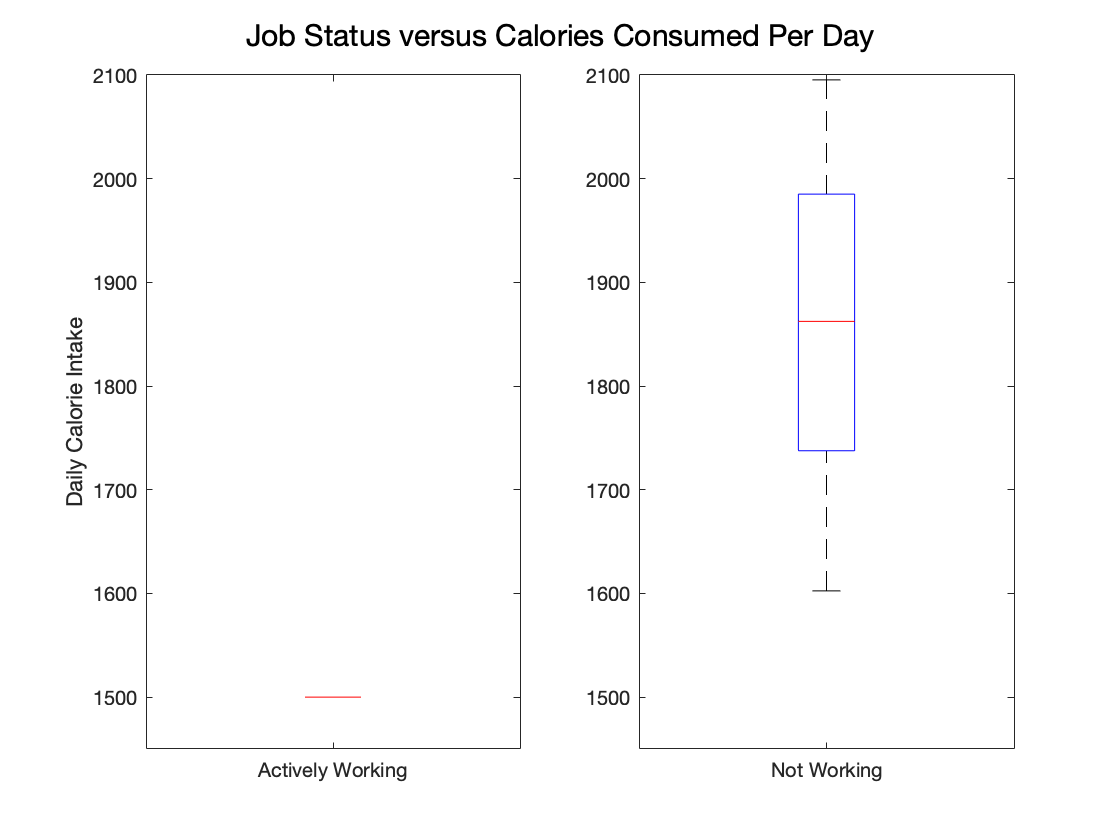


% Visualized
figure, subplot(1,2,1)
boxplot(dataActive.calintake)
xticklabels("Actively Working"), ylabel("Daily Calorie Intake"), ylim([1450, 2100])
subplot(1,2,2)
boxplot(dataInactive.calintake)
xticklabels("Not Working"), ylim([1450, 2100])
sgtitle("Job Status versus Calories Consumed Per Day")

**Figure Caption: **This figure shows the significant difference between the calorie intake of those working versus those not working. It is odd that those actively working have exactly the same calorie intake (N of active workers is 129), however this is what was reported.

## Effects of sleep.

Plenty of research has shown that sleep is important for weight loss. Use the data explore this question. Is amount of sleep correlated with the change in weight? Is amount of sleep different between genders or job types? Is sleep correlated with anything else in the dataset?

% sleep correlated with change in weight (deltaweight)

figure
scatter(data.sleep,data.deltaweight, "b","filled")
title("Average Sleep Per Night versus Change in Weight after 3 months"), xlabel("Average Sleep Per Night (Hours)"), ylabel("Change in Weight After 3 Months (Pounds)")
trend = polyfit(data.sleep, data.deltaweight, 1)

trend =    -0.9393    7.2804


hold on
plot(xlim, xlim*trend(1) + trend(2), 'r--', 'linewidth', 2)
hold off
% acquire R value, determine the correlation coefficient
[rSleepW, pSleepW] = corrcoef([data.sleep, data.deltaweight]);
r2SleepW= rSleepW(1,2)^2;
% R squared is percentage of variation explained by linear regression
fprintf("The Slope is 99%% statistically significant with a p value of %d.\nThe R^2 value of %d implies that predictive power is low.",pSleepW(1,2),r2SleepW)

The Slope is 99% statistically significant with a p value of 8.735204e-04.
The R^2 value of 4.377274e-02 implies that predictive power is low.


% Sleep Association with Gender

trend = polyfit(data.sleep, data.deltaweight, 1)

trend =    -0.9393    7.2804


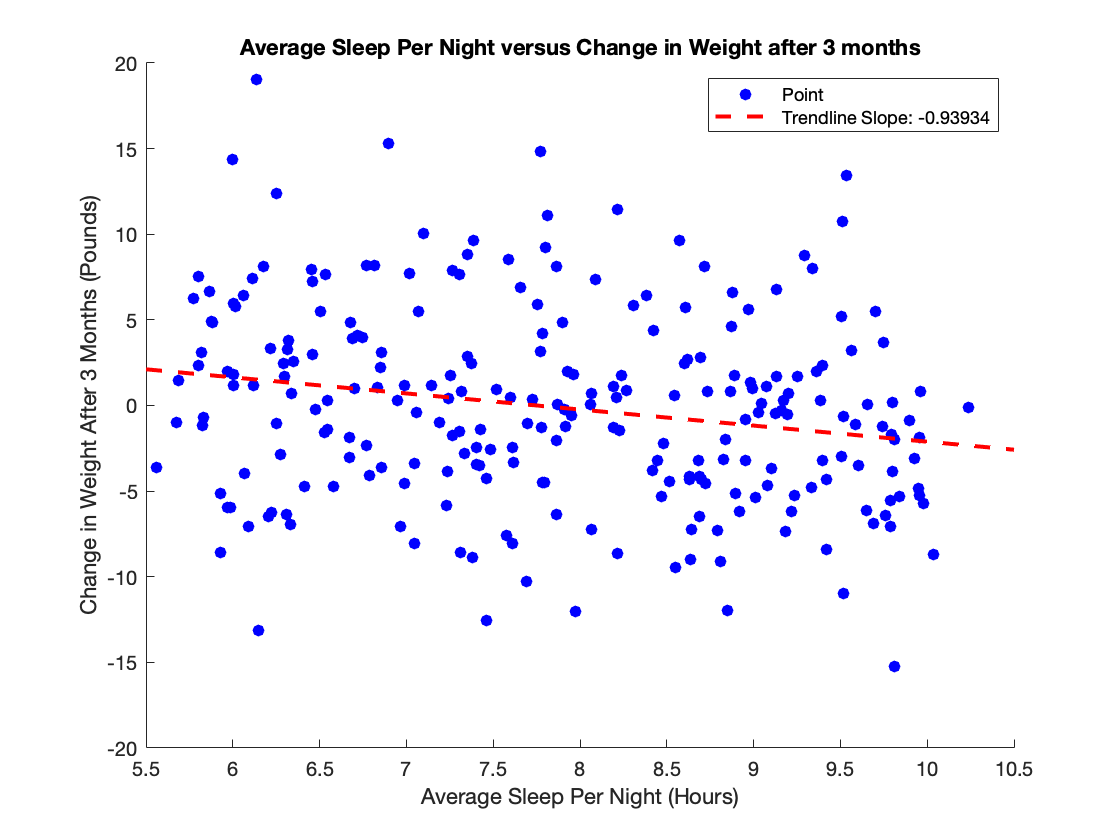

hold on
plot(xlim, xlim*trend(1) + trend(2), 'r--', 'linewidth', 2)
legend("Point",strcat("Trendline Slope: ",string(trend(1))))
hold off

**Figure Caption: **This graph displays the average sleep per night in hours versus the change in weight after the 3 months. Displayed is a negative trendline which shows the trend slope being -0.93934. The Data is statically significant with a p value of 0.0009, and the R^2 value of 0.0438 implies the predictive power of the trendline is low.

% sleep difference between gender and job types

% difference in sleep between male and female
% simple T test
[~, psg]=ttest2(data.sleep(strcmpi(data.gender,'Male'),:),data.sleep(strcmpi(data.gender,'Female'),:));
% p value is high so:
fprintf("The average sleep between genders are statistically the same with a confidence of 99%% due to a high p value of %.3f.",psg)

The average sleep between genders are statistically the same with a confidence of 99% due to a high p value of 0.298.

% between active with job or inactive
[~, psj]=ttest2(data.sleep(strcmpi(data.jobstatus,'Active'),:),data.sleep(strcmpi(data.jobstatus,'Inactive'),:));
% p value is high so:
fprintf("The average sleep between active workers and people without jobs (inactive) are statistically the same with a confidence of 99%% due to a high p value of %.3f.",psj)

The average sleep between active workers and people without jobs (inactive) are statistically the same with a confidence of 99% due to a high p value of 0.236.



% Anything else in dataset?
for i=2:width(data) % excluding ID#
    if isnumeric(table2array(data(1,i)))==1 && i~=10 % make sure columns are numeric and not matching sleep
    trendall = polyfit(table2array(data(:,i)),data.sleep,1);
    [rAll, pAll] = corrcoef([data.sleep, table2array(data(:,i))]);
    if pAll(1,2)<0.01
        fprintf("%s has a trendline slope of %f, with a 99%% confiendce and p value of %f, and a correlation R^2 value of %f.\n",data.Properties.VariableNames{i},trendall(1),pAll(1,2),rAll(1,2)^2)
    end
    end
end

steps has a trendline slope of 0.000290, with a 99% confiendce and p value of 0.008215, and a correlation R^2 value of 0.027832.
deltaweight has a trendline slope of -0.046600, with a 99% confiendce and p value of 0.000874, and a correlation R^2 value of 0.043773.


## Combining values.

In class we talked about inter-correlations between features when building linear models. We know that gender has effects on exercise preference and jobtype effects the number of steps. One way to aleviate those issues is to use domain knowledge to create summary values. We know from biology that what's really important for weight loss is creating a calorie deficit. We know from the data how many colories they consumed but not how much they expended. We can estimate calories expended from the basal metabolic rate and calorie expenditure from exercise.

Calculate the Basal Metabolic Rate (BMR) as follows (https://globalrph.com/medcalcs/harris-benedict-basal-metabolic-rate-calorie-calc/ ) :

- BMR calculation for men (metric): BMR = 66.47 + ( 13.75 x weight in kg ) + ( 5.003 x height in cm ) - ( 6.755 x age in years )

- BMR calculation for women (metric): BMR = 655.1 + ( 9.563 x weight in kg ) + ( 1.850 x height in cm ) - ( 4.676 x age in years )

Calculate the calories expended during aerobic and resistance exercises as follows (values approximated from: [https://journals.lww.com/acsm-msse/Fulltext/2011/08000/2011_Compendium_of_Physical_Activities__A_Second.25.aspx](https://journals.lww.com/acsm-msse/Fulltext/2011/08000/2011_Compendium_of_Physical_Activities__A_Second.25.aspx) ):

- Calories expended during aerobic exercise: **7** * ( weight in kg ) *  ( time in hours per day)

- Calories expended during resistance exercise: **6** * ( weight in kg ) *  ( time in hours per day)

% Calculate the Basal Metabolic Rate (BMR) of each person. Take care to
% convert units as necessary.
basalcalories = zeros(length(data.id),1);


% convert pounds to kg: 1pd = 0.453592kg
% convert height to cm: 1in = 2.54cm

for i=1:length(data.id) % For everyone first
    if strcmpi(data.gender(i),"Male") % for male
        basalcalories(i,1) = 66.47+(13.75*data.initweight(i)*0.453592)+(5.003*data.height(i)*2.54)-(6.755*data.age(i));
    else % For not male (Female)
        basalcalories(i,1) = 655.1+(9.563*data.initweight(i)*0.453592)+(1.850*data.height(i)*2.54)-(4.676*data.age(i));
    end
    
end

% Display the basalcalories of the first 5 people.
for i=1:5
    fprintf("Basal calories for patient %d: %f\n",i,basalcalories(i,1))
end

Basal calories for patient 1: 1439.988055
Basal calories for patient 2: 1626.904766
Basal calories for patient 3: 1341.429844
Basal calories for patient 4: 1343.280695
Basal calories for patient 5: 1357.146678




% Calculate estimated amount of calories expended during aerobic excercise
% and resistence excercise for each person. Take care to convert units as necessary.

excercisecalories = zeros(length(data.id),1);


% exercise time is in minutes per week, change to hours/day (1/7)(1/60)
for i=1:length(data.id) % For everyone first
    aerobic = 7*data.initweight(i)*0.453592*data.timecardio(i)/7/60;
    resistance = 6*data.initweight(i)*0.453592*data.timeresist(i)/7/60;
    excercisecalories(i,1) = aerobic+resistance; 
end

% Display the exercisecalories of the first 5 people.
for i=1:5
    fprintf("Exercise calories for patient %d: %f\n",i,excercisecalories(i,1))
end

Exercise calories for patient 1: 43.720117
Exercise calories for patient 2: 45.300360
Exercise calories for patient 3: 38.664551
Exercise calories for patient 4: 43.253868
Exercise calories for patient 5: 37.100097


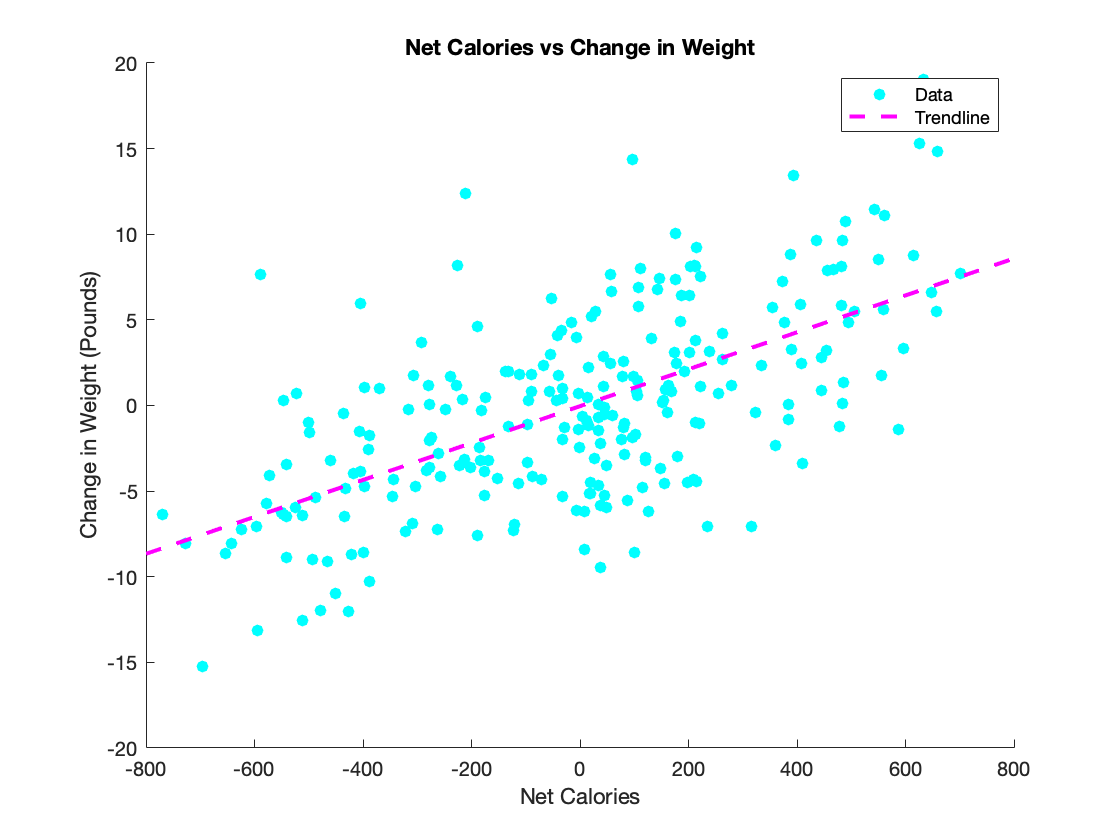

% Now use these two values (and one from the dataset) to estimate the
% net calorie change. (subtract total calorie expenditure from calorie
% intake)

netcalories = zeros(length(data.id),1);
for i=1:length(data.id) % For everyone first
     netcalories(i,1) = data.calintake(i)-basalcalories(i,1)-excercisecalories(i,1);
end

% How well does netcalories correlate with the change in weight?

figure
scatter(netcalories,data.deltaweight,'cyan','filled')
hold on 
title("Net Calories vs Change in Weight"), xlabel("Net Calories"), ylabel("Change in Weight (Pounds)")
trend = polyfit(netcalories, data.deltaweight, 1);
plot(xlim, xlim*trend(1) + trend(2), 'm--', 'linewidth', 2)
legend("Data","Trendline")
hold off

**Figure Caption: **This graph shows the correlation between the net calories per day versus the change in weight after the 3 months. There is a clear trend here, with over a 99% confidence with a pvalue of 6.47E-28. The R^2 value of 0.3839 shows there is solid predicting power

[rcw, pcw] = corrcoef([netcalories, data.deltaweight]);
r2cw= rcw(1,2)^2

r2cw = 0.3839

## Build a model

Use all available information for each subjec to build a model to predict the change in weight for each subject. Plot your predictions versus reality. Calculate the R^2 and discuss what it implies. Discuss the effect sizes that you calculate and their relevance to weight loss.

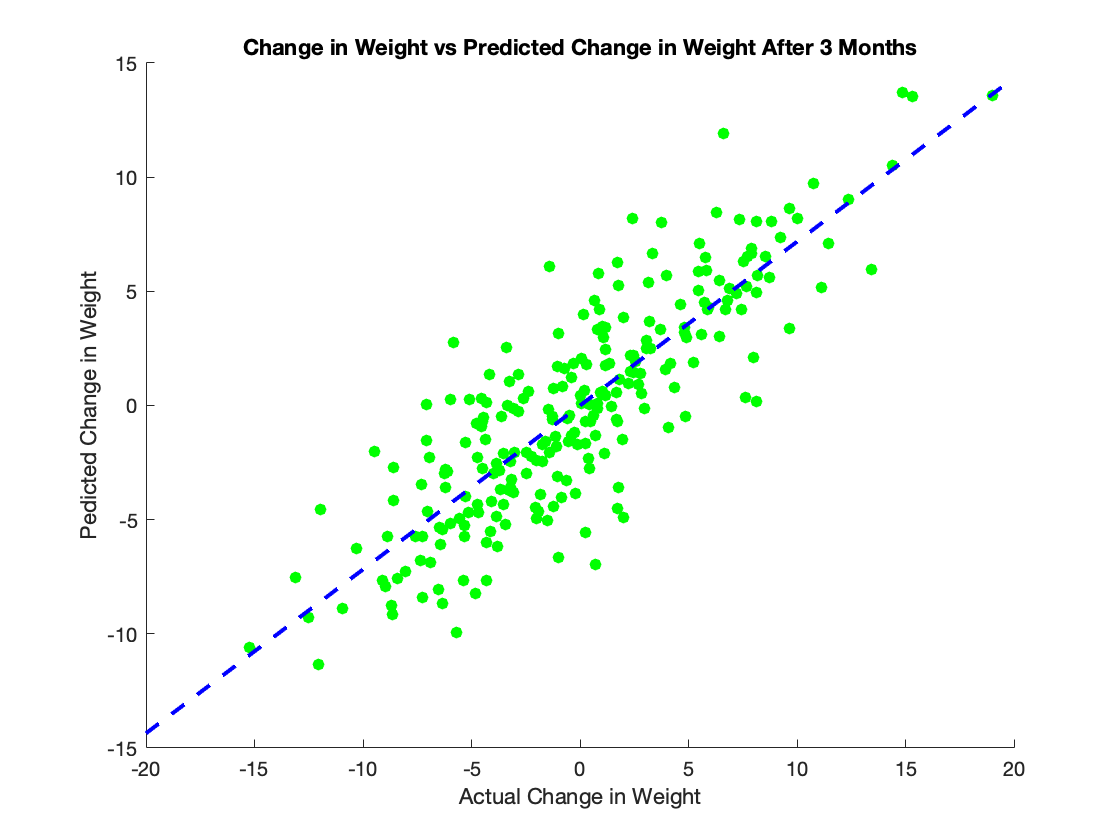

X = [data.initweight, data.steps, data.timeresist, data.timecardio, data.age, data.height, strcmp(data.gender,"Male"), data.sleep, data.calintake, ...
    strcmp(data.jobstatus,"Active")];

% multi linear regression using the total dataset. Keep in mind gender and jobstatus was
% transformed to 0's and 1's, to make the qualitative data into
% quantitative
w = mvregress(X, data.deltaweight);
%predicted values for delta weight
predDeltaWeight = X*w;
figure
scatter(data.deltaweight, predDeltaWeight,"green","filled")
hold on
title("Change in Weight vs Predicted Change in Weight After 3 Months"), ylabel("Pedicted Change in Weight"), xlabel("Actual Change in Weight")
trend = polyfit(data.deltaweight, predDeltaWeight, 1);
plot(xlim, xlim*trend(1) + trend(2), 'b--', 'linewidth', 2)
hold off

**Figure Caption:** This relates the Actual Change in weight with the predicted change of weight, which is generated from a multi linear regression of all 10 variables (excluding the delta weight normal and the ID). The trendline shown shows the linear esque correlation between these two, in which the trendline has a slope of 0.7176. The R^2 value acquired also is 0.7176, implying there is a strong predictive power for the trendline, with a p value of 2.317E-72. 

[rpw, ppw] = corrcoef([data.deltaweight, predDeltaWeight]);
r2pw= rpw(1,2)^2

r2pw = 0.7176

w'

ans =    -0.0179    0.0022   -0.1560   -0.1136    0.0917   -0.1816   -0.9806   -1.1659    0.0121   -2.1264


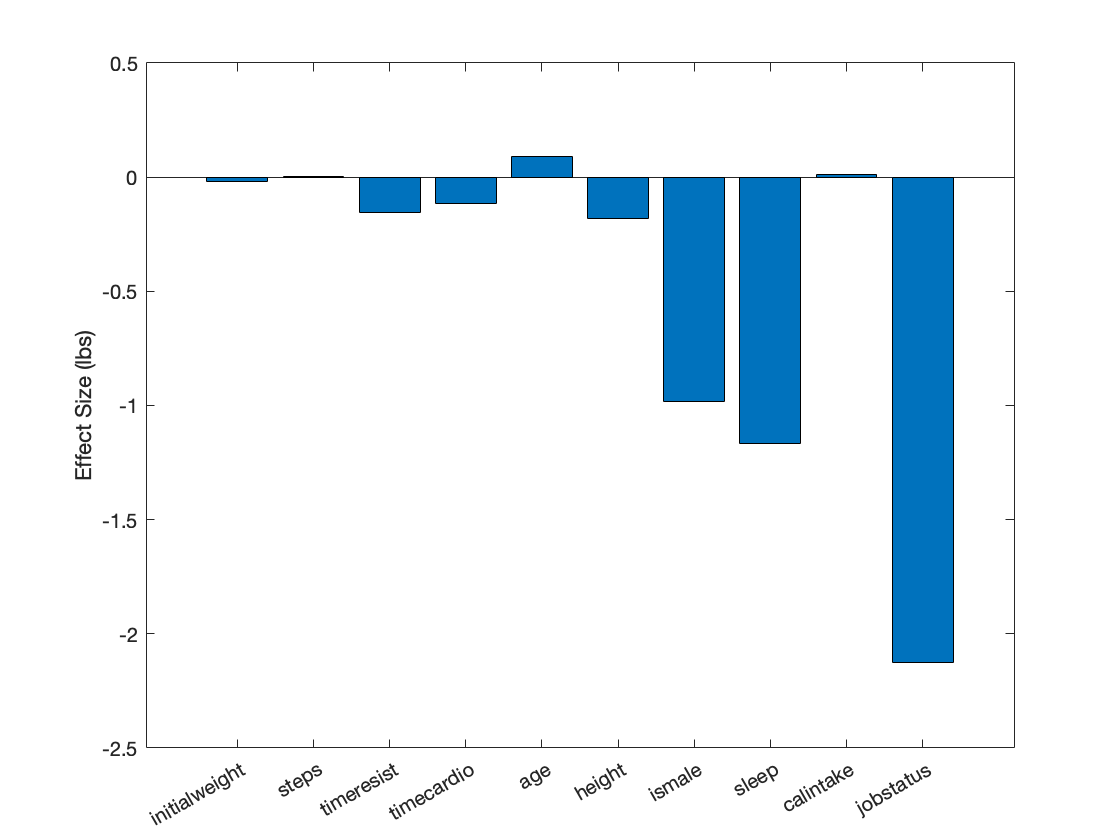

figure
bar(w)
ylabel('Effect Size (lbs)')
set(gca, 'xticklabel', {'initialweight', 'steps', 'timeresist', 'timecardio', 'age', 'height', 'ismale', 'sleep', 'calintake', 'jobstatus'})

**Figure Caption: **Above shows the results of the multivariate regression. These essentially are the weighing effects of each variable on the change in weight output. The jobstatus is calculated to weigh the most on the negative change in weight.